# Testing april tag localization

initialize ros

init_ROS();

Shutting down global node /matlab_global_node_66558 with NodeURI http://192.168.16.78:50523/ and MasterURI http://192.168.16.71:11311/.
Initializing global node /matlab_global_node_85054 with NodeURI http://192.168.16.78:50595/ and MasterURI http://192.168.16.71:11311/.
ROS initialization complete! :-)


## Create cam object

calib_params = load("camera_calibration/calib_1024x768/cameraParams2.mat");
cam_intrinsics = calib_params.cameraParams2.Intrinsics;
cam = Camera_ROS_ben(cam_intrinsics);

pause(1);

## get image from camera and display tag detection

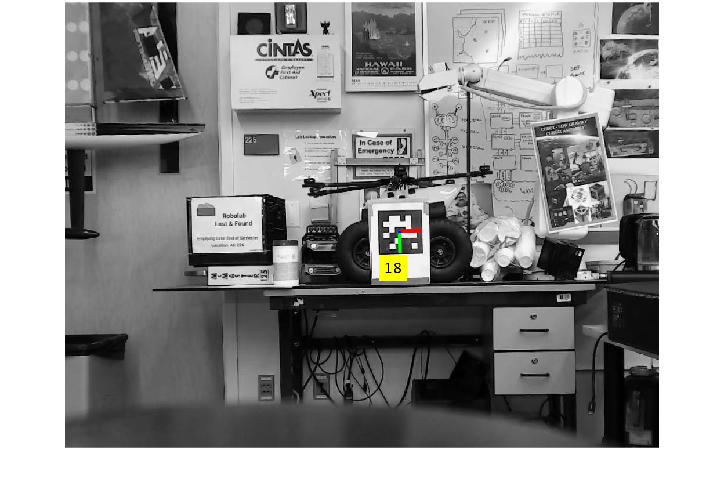

img = rgb2gray(cam.get_image_raw());
[img_undistort, new_center] = cam.undistort_image(img);

img = rgb2gray(cam.get_image_raw());
% display april tag detection
try
    [num_tags, tag_ids, tag_img_corners, detected_tags] = AprilTags.detect_tags_in_image(img_undistort, cam_intrinsics);
    tag_area = polyarea(tag_img_corners(:,1), tag_img_corners(:,2));
    [img_undistort, new_center] = cam.undistort_image(img);
    img_tags_draw = AprilTags.draw_tags_on_image(img_undistort, cam_intrinsics, num_tags, tag_ids, tag_img_corners, detected_tags);
    figure
    imshow(img_tags_draw);
catch
    figure
    imshow(img_undistort);
end

## 3d plot

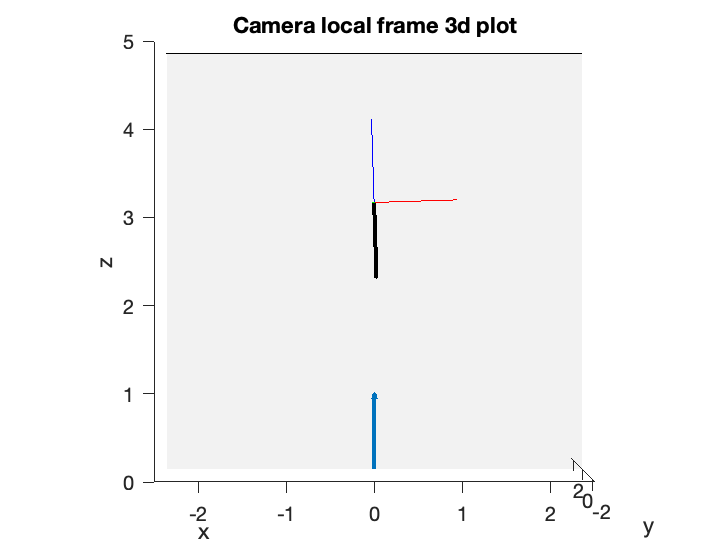

figure; hold on
% plot styling
axis equal
camproj("perspective")
xlim([-2.5 2.5]); ylim([-2.5 2.5]); zlim([0 5])
xlabel("x"); ylabel("y"); zlabel("z")
view([0 0.01])
title("Camera local frame 3d plot")

% plot patch for x-z plane
s = 5;
patch([s -s -s s], [0 0 0 0], [s s -s -s], [s s -s -s], "FaceColor", "k", "FaceAlpha", 0.05)

% plot camera heading vector at [0,0,0]
quiver3(0, 0, 0, 0, 0, 1, LineWidth=2)

% plot apriltag axes in space
tag_quat = rotm2quat(detected_tags.Rotation);
plotTransforms(detected_tags.Translation, tag_quat)

% plot projected april tag normal vector
tag_x = detected_tags.Translation(1);  % positive right
tag_y = -detected_tags.Translation(2); % positive down
tag_z = detected_tags.Translation(3);  % positive away from cam
tag_rot_x = detected_tags.Rotation(:, 1);
tag_rot_z = detected_tags.Rotation(:, 3);
% quiver3(tag_x, tag_y,tag_z, -tag_poses.Rotation(1,3), -tag_poses.Rotation(2,3), -tag_poses.Rotation(3,3), Color="k")
quiver3(tag_x, 0,tag_z, -detected_tags.Rotation(1,3), 0, -detected_tags.Rotation(3,3), Color="k", LineWidth=2)

## 2d plot in cam reference frame

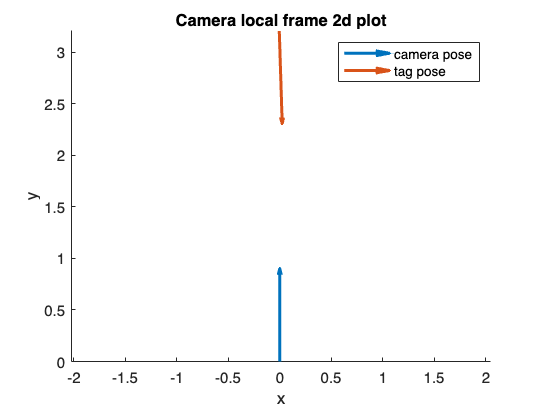

figure; hold on; axis equal
% plot styling
% xlim([-2.5 2.5]); ylim([0 5]); 
xlabel("x"); ylabel("y");

cam_pose_cam_frame = Pose2d(Translation2d, Rotation2d.from_degrees(90));
quiver_pose(cam_pose_cam_frame)
tag_pose_cam_frame = Pose2d(Translation2d(tag_x, tag_z), Rotation2d(-detected_tags.Rotation(1,3), -detected_tags.Rotation(3,3)));
quiver_pose(tag_pose_cam_frame)

title("Camera local frame 2d plot")
legend("camera pose", "tag pose")

## 2d transform to tag reference frame

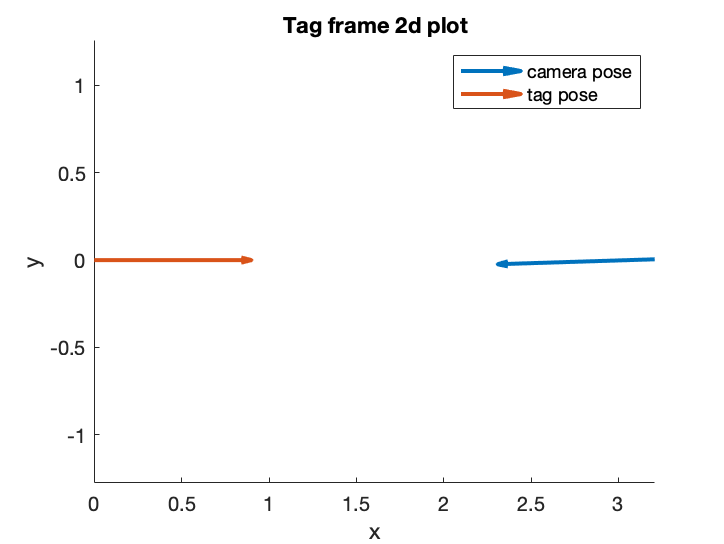

figure; hold on; axis equal
% plot styling
% xlim([-2.5 2.5]); ylim([0 5]); 
xlabel("x"); ylabel("y");

tag_pose_tag_frame = Pose2d(Translation2d, Rotation2d);
% cam_pose_tag_frame = Pose2d(tag_pose_cam_frame.translation.unary_minus, ...
%        tag_pose_cam_frame.rotation.rotate_by(Rotation2d.from_degrees(180)))
cam_to_tag_transf = Transform2d(tag_pose_cam_frame.translation.unary_minus, ...
           tag_pose_cam_frame.rotation.rotate_by(Rotation2d.from_degrees(180)));
cam_pose_tag_frame = cam_pose_cam_frame.transform_by(cam_to_tag_transf);


quiver_pose(cam_pose_tag_frame)
quiver_pose(tag_pose_tag_frame)

title("Tag frame 2d plot")
legend("camera pose", "tag pose")

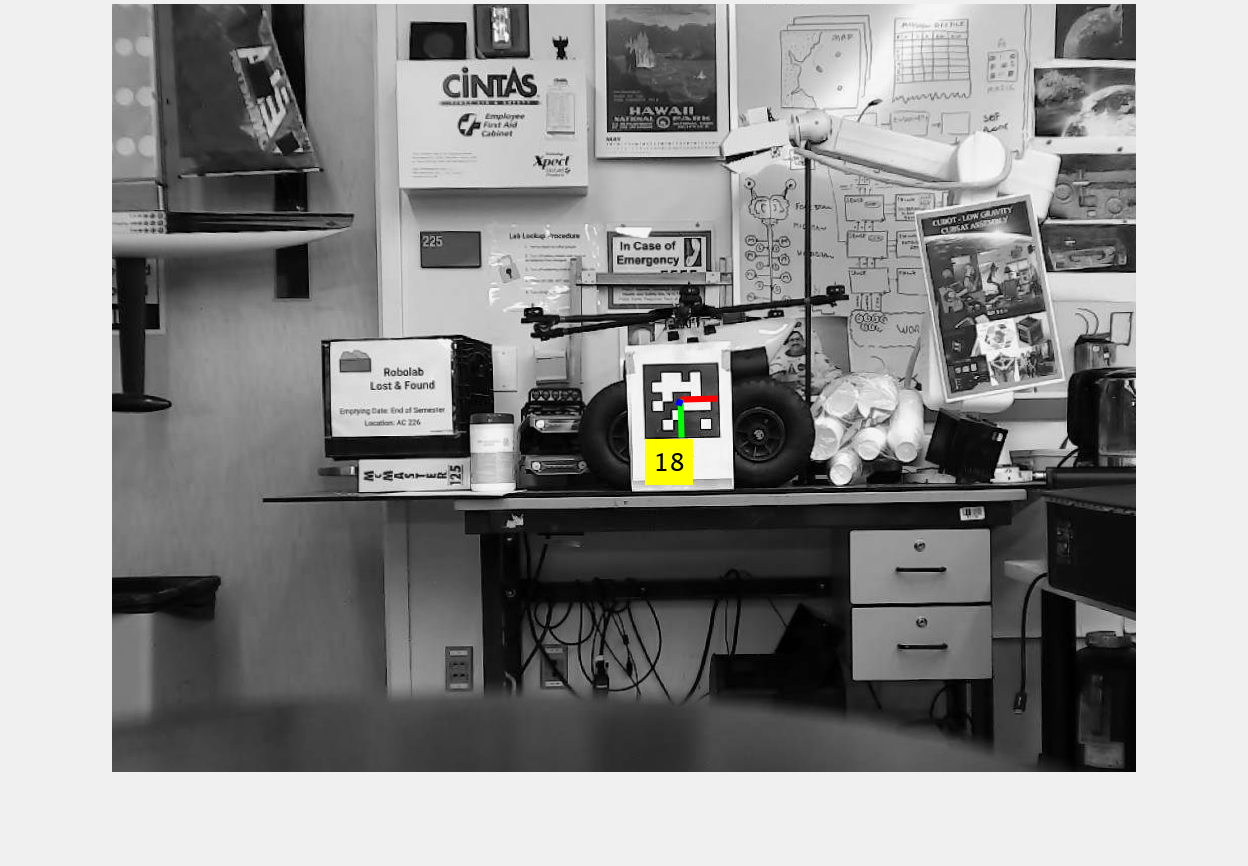

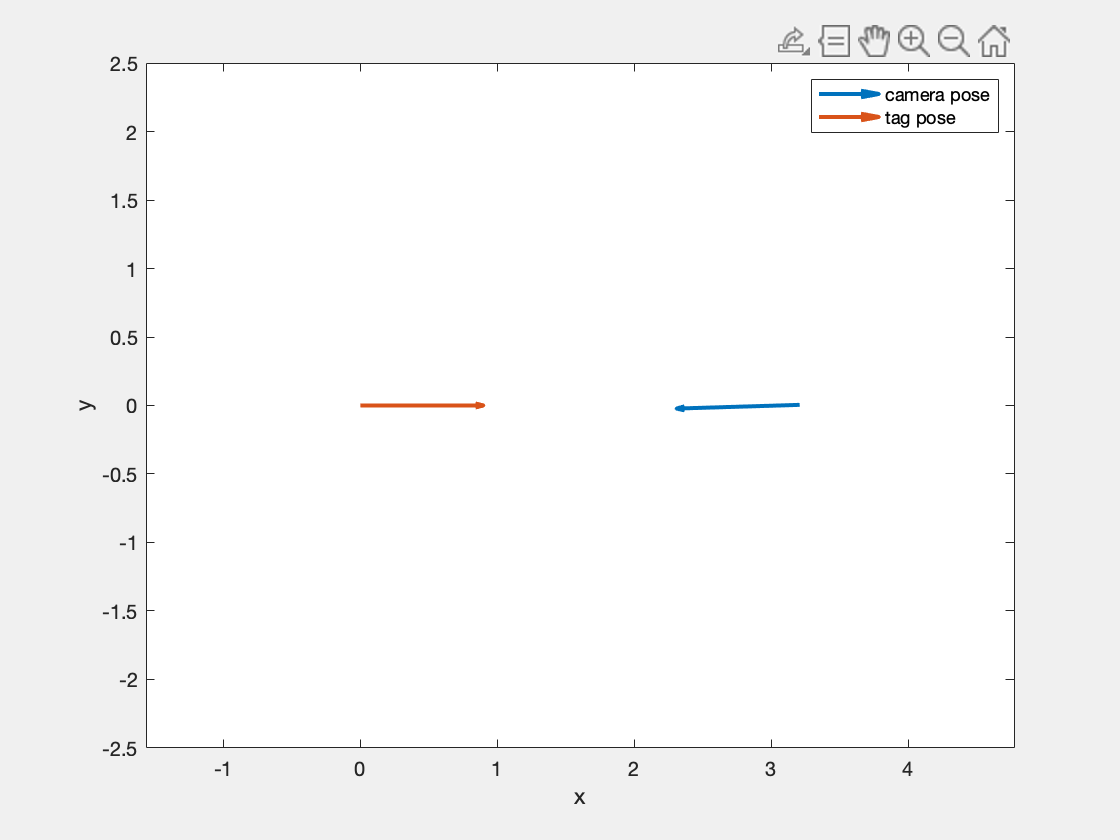

Error using figure
Argument must be a Figure object or a positive integer.

tag_pose = Pose2d.from_xydeg(0, 0, 0);

% loop rate obj
r = rateControl(5); % Hz

% initialize view with black img
f1 = figure;
set(gcf,'Visible','on')

img_view = imshow(zeros(768, 1024));
title("Minion View")

f2 = figure;
set(gcf,'Visible','on')
tag_pose_tag_frame = Pose2d(Translation2d, Rotation2d);
title("Tag frame 2d plot")

while true
    img = rgb2gray(cam.get_image_raw());
    [img_undistort, new_center] = cam.undistort_image(img);
    % only display the img if no tags detected
    [num_tags, tag_ids, tag_img_corners, detected_tags] = AprilTags.detect_tags_in_image(img_undistort, cam_intrinsics);

    if ~num_tags
        colormap bone
        rgbImage = ind2rgb(img_undistort, colormap);
        set(img_view, "Cdata", rgbImage);
        drawnow();
        continue
    end
    tag_area = polyarea(tag_img_corners(:,1), tag_img_corners(:,2));
    [img_undistort, new_center] = cam.undistort_image(img);
    img_tags_draw = AprilTags.draw_tags_on_image(img_undistort, cam_intrinsics, num_tags, tag_ids, tag_img_corners, detected_tags);
    
    figure(f1)
    set(img_view, "Cdata", img_tags_draw);
    drawnow();
    
    figure(f2)     
    % plot april tag localization
%     cam_pose = get_cam_pose_global(detected_tags(1), tag_pose);
    cam_pose = get_cam_pose_tag_frame(detected_tags(1));
    quiver_pose(cam_pose)
    hold on;
    quiver_pose(tag_pose)
    hold off;

    % plot styling
    xlim([-2.5 2.5]); ylim([-2.5 2.5]);
    xlabel("x"); ylabel("y");
    axis equal
    legend("camera pose", "tag pose")
    drawnow();
end

function quiver_pose(pose)
    quiver(pose.translation.val_x, pose.translation.val_y,...
       pose.rotation.vec_cos, pose.rotation.vec_sin, "LineWidth", 2);
end

function cam_pose_global = get_cam_pose_global(detected_tag, tag_pose)
%%CAM_POSE_GLOBAL returns a Pose2d of the camera's pose 
%%in the global reference frame.
    cam_pose_tag_frame = get_cam_pose_tag_frame(detected_tag);
%     tag_transf = Transform2d(tag_pose.translation, tag_pose.rotation);
    tag_transf = Transform2d(tag_pose.translation, tag_pose.rotation);
    cam_pose_global = cam_pose_tag_frame.transform_by(tag_transf);
end

function cam_pose_tag_frame = get_cam_pose_tag_frame(detected_tag)
%%CAM_POSE_TAG_FRAME returns a Pose2d of the camera's pose in an AprilTag's
%%frame of reference.
    tag_x = detected_tag.Translation(1);  % positive right
    tag_z = detected_tag.Translation(3);  % positive away from cam
    % get the rotation of the tag's normal vector projected into the xz plane 
    tag_normal_projected_rot = Rotation2d(-detected_tag.Rotation(1,3), ...
                                          -detected_tag.Rotation(3,3));
    % get tag pose in camera frame from apriltag pose
    tag_pose_cam_frame = Pose2d(Translation2d(tag_x, tag_z), ...
        tag_normal_projected_rot);

    % camera's pose in the camera frame is [0, 0, 90º]
    cam_pose_cam_frame = Pose2d(Translation2d, Rotation2d.from_degrees(90));
    
    % Get 2d transform that sends poses in the cam frame to poses in the
    % tag frame
    cam_to_tag_transf = Transform2d(tag_pose_cam_frame.translation.unary_minus(), ...
               tag_pose_cam_frame.rotation.rotate_by(Rotation2d.from_degrees(180)));

    % Transform camera pose by that 2d transform to get the camera pose in
    % the tag's frame of reference
    cam_pose_tag_frame = cam_pose_cam_frame.transform_by(cam_to_tag_transf);
end